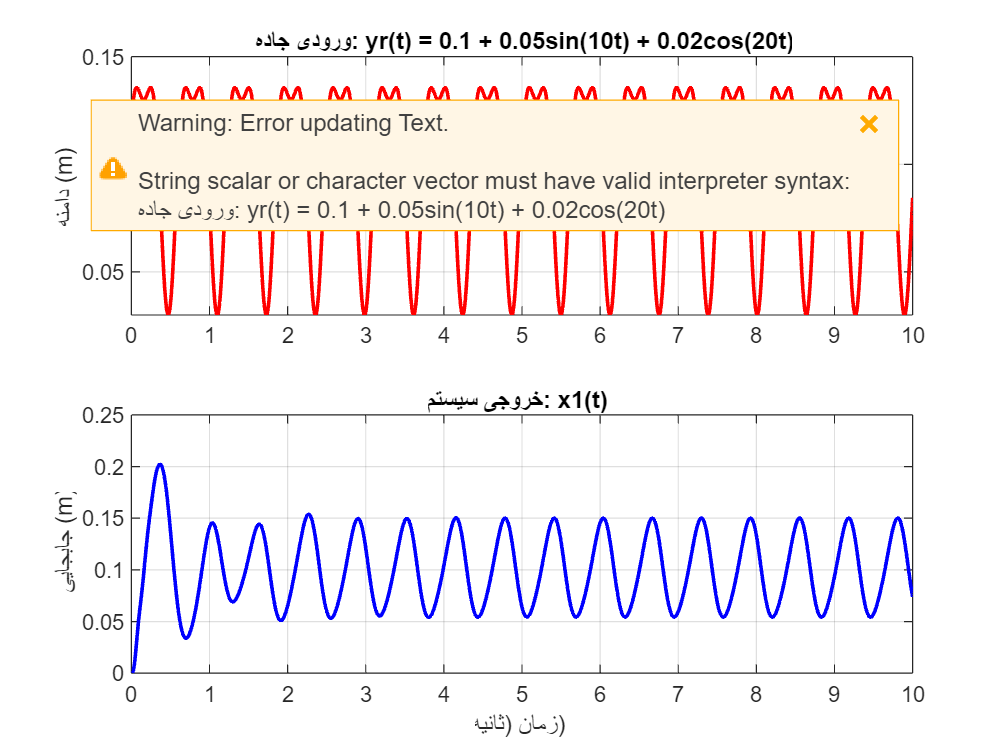

clc; clear; close all;

A = [0,      0,     1,      0;
     0,      0,     0,      1;
    -50,    50,   -3.3333,   3.3333;
     300, -3300,    20,    -20];

B = [0; 0; 0.003333; -0.02];
W = [0; 0; 0; 3000];       

C = [1,0, 0, 0];          
D = 0;

t = 0:0.005:10; 
yr = 0.1 + 0.05*sin(10*t) + 0.02*cos(20*t);

sys_road = ss(A, W, C, D);

[x2, t_out] = lsim(sys_road, yr, t);

figure('Color', 'w');

subplot(2,1,1);
plot(t, yr, 'r', 'LineWidth', 1.5);
grid on;
title('ورودی جاده: yr(t) = 0.1 + 0.05sin(10t) + 0.02cos(20t)', 'Interpreter', 'latex');
ylabel('دامنه (m)');

subplot(2,1,2);
plot(t_out, x2, 'b', 'LineWidth', 1.5);
grid on;
title('خروجی سیستم: x1(t) ', 'Interpreter', 'latex');
xlabel('زمان (ثانیه)');
ylabel('جابجایی (m)');

disp('تابع تبدیل خروجی به ورودی کنترلی (Gu):');

تابع تبدیل خروجی به ورودی کنترلی (Gu):


[num, den] = ss2tf(A, B, C, D);
tf_u = tf(num, den)

tf_u =
 
         0.003333 s^2 - 6e-06 s + 9.999
  --------------------------------------------
  s^4 + 23.33 s^3 + 3350 s^2 + 1e04 s + 1.5e05
 
Continuous-time transfer function.
Model Properties
